[x2, y2, z2, vel2, Gx2, Gy2, Gz2] = section2(0,50,125);
plot3(x2,y2,z2)
xlabel("x (m)")
ylabel("y (m)")
zlabel("z (m)")
xlim([0 300])
ylim([0 300])
zlim([0 125])
hold on
plot3(x2,y2,z2)
[x3, y3, z3, vel3, Gx3, Gy3, Gz3] = section3(x2(end),y2(end),z2(end),10);
plot3(x3,y3,z3)
hold on
[x4,y4,z4,vel4,Gx4,Gy4,Gz4] = loopPath(x3(end),y3(end),z3(end),9,1);
plot3(x4,y4,z4)
[x5, y5, z5, vel5, Gx5, Gy5, Gz5] = section3(x4(end),y4(end),z4(end),10);
plot3(x5,y5,z5)
[x6, y6, z6, vel6, Gx6, Gy6, Gz6] = launch(x5(end),y5(end),z5(end),10);
plot3(x6,y6,z6)
parabolicPos = [x6(end),y6(end),z6(end)];
parabolicVel = [vel6(end)*sqrt(2)/2,0,vel6(end)*sqrt(2)/2];
[x7, y7, z7, vel7, Gx7, Gy7, Gz7, vf] = Parabola(parabolicVel,parabolicPos);
plot3(x7,y7,z7)
[x8, y8, z8, vel8, Gx8, Gy8, Gz8] = landing1(x7(end),y7(end),z7(end),10);
plot3(x8,y8,z8)
[x9, y9, z9, vel9, Gx9, Gy9, Gz9] = section1(x8(end),y8(end),z8(end),5);
plot3(x9,y9,z9)
[x10, y10, z10, vel10, Gx10, Gy10, Gz10] = linearDown(x9(end),y9(end),z9(end),2);
plot3(x10,y10,z10)
[x11, y11, z11, vel11, Gx11, Gy11, Gz11] = landing2(x10(end),y10(end),z10(end),15);
plot3(x11,y11,z11)
[x12, y12, z12, vel12, Gx12, Gy12, Gz12] = launch(x11(end),y11(end),z11(end),15);
plot3(x12, y12, z12)
[x13, y13, z13, vel13, Gx13, Gy13, Gz13] = linearUp(x12(end), y12(end), z12(end),2);
plot3(x13, y13, z13)
[x14, y14, z14, vel14, Gx14, Gy14, Gz14] = section4(x13(end), y13(end), z13(end),30);
plot3(x14, y14, z14)
[x15, y15, z15, vel15, Gx15, Gy15, Gz15] = bankedTurn(x14(end), y14(end), z14(end), vel14(end), 30);
plot3(x15, y15, z15)
[x16, y16, z16, vel16, Gx16, Gy16, Gz16] = sectionDown(x15(end), y15(end), z15(end),5)

x16 =   139.3975  139.3973  139.3969  139.3961  139.3950  139.3936  139.3918  139.3898  139.3874  139.3848  139.3818  139.3785  139.3749  139.3709  139.3667  139.3621  139.3573  139.3521  139.3466  139.3408  139.3347  139.3283  139.3215  139.3145  139.3071  139.2995  139.2915  139.2832  139.2746  139.2658  139.2566  139.2471  139.2372  139.2271  139.2167  139.2060  139.1950  139.1836  139.1720  139.1601  139.1479  139.1353  139.1225  139.1094  139.0960  139.0822  139.0682  139.0539  139.0393  139.0244


y16 =     55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55    55


z16 =   111.1323  111.1720  111.2116  111.2513  111.2909  111.3306  111.3702  111.4098  111.4494  111.4890  111.5285  111.5681  111.6076  111.6470  111.6865  111.7259  111.7652  111.8046  111.8439  111.8831  111.9223  111.9614  112.0005  112.0396  112.0785  112.1175  112.1563  112.1951  112.2338  112.2725  112.3111  112.3496  112.3880  112.4264  112.4647  112.5028  112.5409  112.5790  112.6169  112.6547  112.6925  112.7301  112.7676  112.8051  112.8424  112.8796  112.9167  112.9537  112.9906  113.0274


vel16 =    16.4950   16.4714   16.4477   16.4241   16.4004   16.3766   16.3529   16.3291   16.3053   16.2815   16.2576   16.2337   16.2099   16.1860   16.1620   16.1381   16.1141   16.0902   16.0662   16.0422   16.0183   15.9943   15.9703   15.9463   15.9223   15.8983   15.8743   15.8503   15.8263   15.8023   15.7784   15.7544   15.7304   15.7065   15.6826   15.6587   15.6348   15.6109   15.5871   15.5632   15.5394   15.5157   15.4919   15.4682   15.4445   15.4208   15.3972   15.3736   15.3501   15.3265


Gx16 =     0.0000    0.0079    0.0159    0.0238    0.0317    0.0397    0.0476    0.0555    0.0634    0.0713    0.0792    0.0872    0.0951    0.1030    0.1108    0.1187    0.1266    0.1345    0.1423    0.1502    0.1580    0.1658    0.1736    0.1815    0.1893    0.1970    0.2048    0.2126    0.2203    0.2280    0.2358    0.2435    0.2511    0.2588    0.2665    0.2741    0.2817    0.2893    0.2969    0.3045    0.3120    0.3196    0.3271    0.3346    0.3420    0.3495    0.3569    0.3643    0.3717    0.3790


Gy16 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Gz16 =     1.0000    0.9999    0.9996    0.9992    0.9985    0.9976    0.9966    0.9954    0.9940    0.9924    0.9906    0.9886    0.9864    0.9841    0.9815    0.9788    0.9759    0.9728    0.9695    0.9660    0.9623    0.9585    0.9544    0.9502    0.9458    0.9412    0.9364    0.9314    0.9263    0.9210    0.9154    0.9097    0.9038    0.8978    0.8915    0.8851    0.8785    0.8717    0.8647    0.8575    0.8502    0.8427    0.8350    0.8271    0.8191    0.8108    0.8024    0.7939    0.7851    0.7762


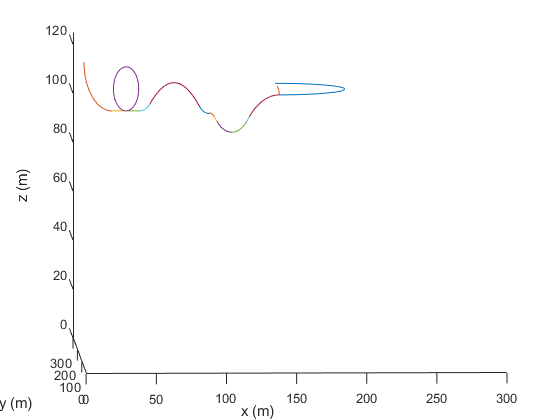

plot3(x16, y16, z16)
hold off

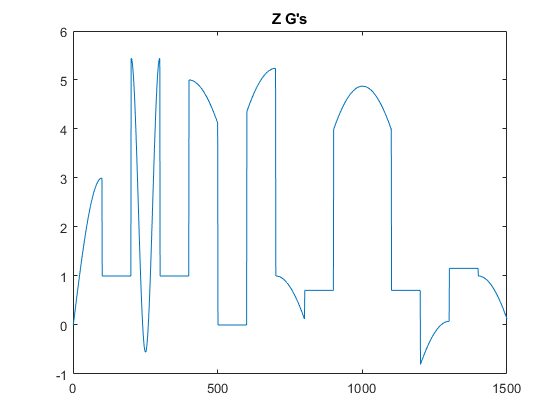




plot([Gz2 Gz3 Gz4 Gz5 Gz6 Gz7 Gz8 Gz9 Gz10 Gz11 Gz12 Gz13 Gz14 Gz15 Gz16])
title("Z G's")
hold off

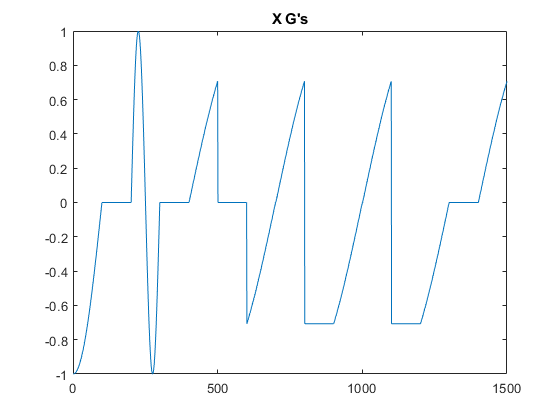

plot([Gx2 Gx3 Gx4 Gx5 Gx6 Gx7 Gx8 Gx9 Gx10 Gx11 Gx12 Gx13 Gx14 Gx15 Gx16])
title("X G's")
hold off

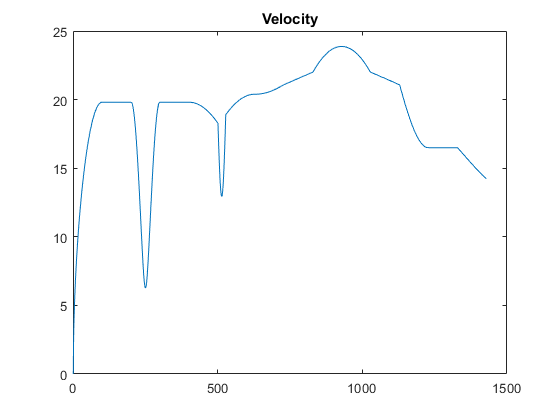

zCoord = [z2 z3 z4 z5 z6 z7 z8 z9 z10 z11 z12 z13 z14];
plot([vel2 vel3 vel4 vel5 vel6 vel7 vel8 vel9 vel10 vel11 vel12 vel13 vel14 vel15 vel16])
title("Velocity")
hold off

function [x, y, z, vel, Gx, Gy, Gz] = section1(xI,yI,zI,radius)
    theta = linspace(pi/2,pi/4,100);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI + radius;
    z = radius.*sin(theta) + zI - radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = 3*cos(pi/2 - theta) - 2;
    Gx = cos(theta);
    Gy = theta .* 0;
%     t = linspace(0,10,100);
%     g = 9.81;
%     x = t.*0 + xI;
%     y = t.*0 + yI;
%     z = -t + zI;
%     vel = sqrt(2 .* g .* (125 - z));
%     Gz = t .* 0;
%     Gx = t .* 0;
%     Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = sectionDown(xI,yI,zI,radius)
    theta = linspace(pi/2,pi/4,100);
    g = 9.81;
    x = radius.*sin(theta) + xI - radius;
    y = theta.*0 + yI;
    z = radius.*cos(theta) + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = 3*cos(pi/2 - theta) - 2;
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section2(xI,yI,zI)
    % circular section, G's occur perpendicular to cart, vert -> flat
    theta = linspace(pi,3*pi/2,100);
    radius = 20;
    g = 9.81;
    x = radius.*cos(theta) + radius;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section3(xI,yI,zI,L)
    % linear section, 1G downwards, propogates in the x direction 
    t = linspace(0,L,100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + 1;
    Gx = t .* 0;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section4(xI,yI,zI,radius)
    % circular section, G's occur perpendicular to cart, 45 degree to flat
    theta = linspace(3*pi/4,pi/2,100);
    g = 9.81;
    x = radius.*cos(theta) + xI + 21.2132;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI - 21.2132;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = -((vel.^2)./(g * radius)) + sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = bankedTurn(xI, yI, zI, vel_in, theta)
    % banked turn, G's in all cartesian directions
    g = 9.81;
    thetaR = deg2rad(theta);
    r = ((vel_in)^2 / g) * cot(thetaR);
    t = linspace(pi/2,-pi/2,100);
    Gx = t.*0;
    Gy = t.*0;
    Gz = t.*0 + 1./cos(thetaR);
    x = r.*cos(t) + xI;
    y = r.*sin(t) + yI + r;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
end
function [x,y,z,V,Gx,Gy,Gz] = loopPath(xI,yI,zI,r,prop)
    %% Setup
    % Note, this currently only calculated velocity correctly
    % if the path is one full loop. I need to add the calculations
    % for the velocity vector for a partial loop.
    h0 = 125; % [m] initial height
    m = 100;  % [kg] particle mass
    g = 9.81; % [m/s^2] gravity
    t = linspace(-pi/2,(prop.*2.*pi)-pi./2,100);
    %% calculating positions
    x = xI + r.*cos(t);
    z = zI + r + r.*sin(t);
    y = yI + 0.*t;         % If you change t to be multiplied by a nonzero number it becomes a helix
    %% velocity and G force calculations
    V = t.*0 + sqrt(2*g*(h0-z));
    N = m*((-sin(t)*g)+((V.^2)/r));
    Gz = t.*0 + N/(m*g);
    Gx = cos(t);
    Gy = t.*0;
    %% output
end
function [x, y, z, vel, Gx, Gy, Gz] = launch(xI,yI,zI,radius)
    % circular section, creates platform for parabolic section
    theta = linspace(3*pi/2,7*pi/4,100);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz, vf] = Parabola(v0,pos0)
    %% Setup of variables and vectors
    t = linspace(0,10,100);
    g = 9.81;
    x = ones(1,length(t)).*4200; % filling with large values
    y = ones(1,length(t)).*4200; % to be trimmed later
    z = ones(1,length(t)).*4200;
    x(1) = pos0(1);
    y(1) = pos0(2);
    z(1) = pos0(3);
    i = 2;
    %% Calculating path with kinematics
    while i <= length(t)
        x(i) = (v0(1)*t(i))+x(1);
        y(i) = (v0(2)*t(i))+y(1);
        z(i) = ((v0(3)*t(i))-(0.5*g*t(i)*t(i)))+z(1);
        if z(i) <= z(1)
            i = length(t);
        end
        i = i + 1;
    end
    %% Trimming position vectors
    x = x(x ~= 4200);   % output, [meters]
    y = y(y ~= 4200);   % output, [meters]
    z = z(z ~= 4200);   % output, [meters]
    vel = sqrt(2*g.*(125-z));
    Gz = t .* 0;
    Gx = t .* 0;
    Gy = t .* 0;
    % z(end) = z(1);
    vf = [v0(1) v0(2) -v0(3)];  % output, [m/s]
end
function [x, y, z, vel, Gx, Gy, Gz] = landing1(xI,yI,zI,radius)
    % circular section, platform for parabolic landing
    theta = linspace(5*pi/4,3*pi/2,100);
    g = 9.81;
    x = radius.*cos(theta) + xI + 7.0711;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 7.0711;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = landing2(xI,yI,zI,radius)
    % circular section, platform for parabolic landing
    theta = linspace(5*pi/4,3*pi/2,100);
    g = 9.81;
    x = radius.*cos(theta) + xI + 10.6066;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 10.6066;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = linearDown(xI,yI,zI,L)
    t = linspace(0,L,100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = -t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + sqrt(2)/2;
    Gx = t .* 0 - sqrt(2)/2;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = linearUp(xI,yI,zI,L)
    t = linspace(0,L,100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + sqrt(2)/2;
    Gx = t .* 0 - sqrt(2)/2;
    Gy = t .* 0;
end